## TOPIC 7: Building solutions to problems, part 2

ENGR105, 9/24/20

### Tinkering with fundamental MATLAB operations

***Practice problem: ***

- We want to simulated rolling one dice until three of one number in a row show up. 

- Repeat this simulation 1000 times. 

- Plot the frequency that each side (1-6) is the side that comes up 3 times in a row. Plot the distribution of turns required to achieve three in a row.

#### 1) Functions

- **What are functions good for?** Functions are ideal for consolidating your code into a standalone collection that can be executed in response to some inputs into the code.

- **When should you use a function?** You should use a function when need to repeat tasks with different inputs. Functions provide an organized way to perform a series of tasks with only the input specified.

- **How do inputs and outputs work?** You specify these in the function declaration -- when you call your function, you should match the form of your declaration. **See practice code.**

- **What if you do not care about all outputs?** You can disregard inputs with `~`.

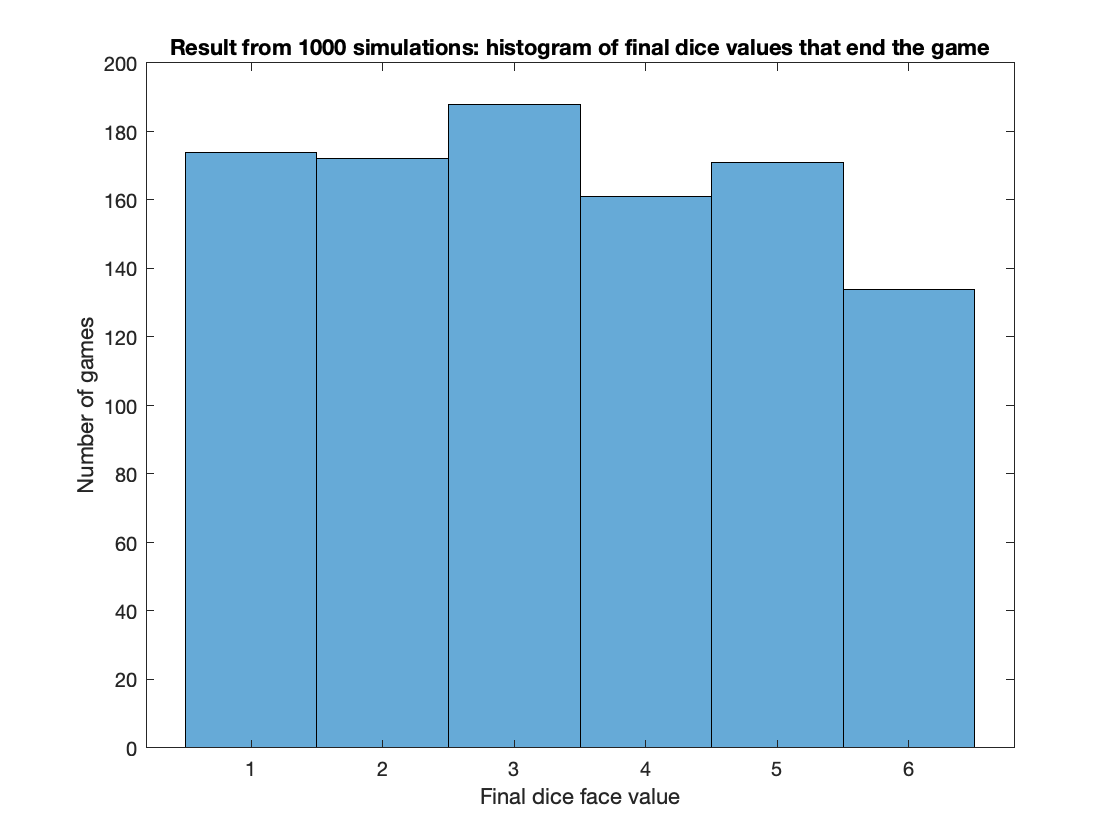

%The final form of the practice problem from class

% Preallocate storage vectors 
numTurns = zeros(1,1000);      % Store requred number of turns from k-th game
diceFaceValue = zeros(1,1000); % Store final dice face value from the k-th game 
for k = 1:1000
    [numTurns(k), diceFaceValue(k)] = diceRollSimulator(3,6);
end
histogram(diceFaceValue)
ylabel('Number of games')
xlabel('Final dice face value')
title('Result from 1000 simulations: histogram of final dice values that end the game')

#### 2) Conditional statements

- **How does the flow of information through conditional statements work?** Conditional statements provide structure that enables certain lines of code to run only if some logical condition is met.

- **When should you have an **`else`** statement?** You should include an else statement if you wish certain lines of code to run if all conditional statements provided in an `if-elseif-else` statement are not true.

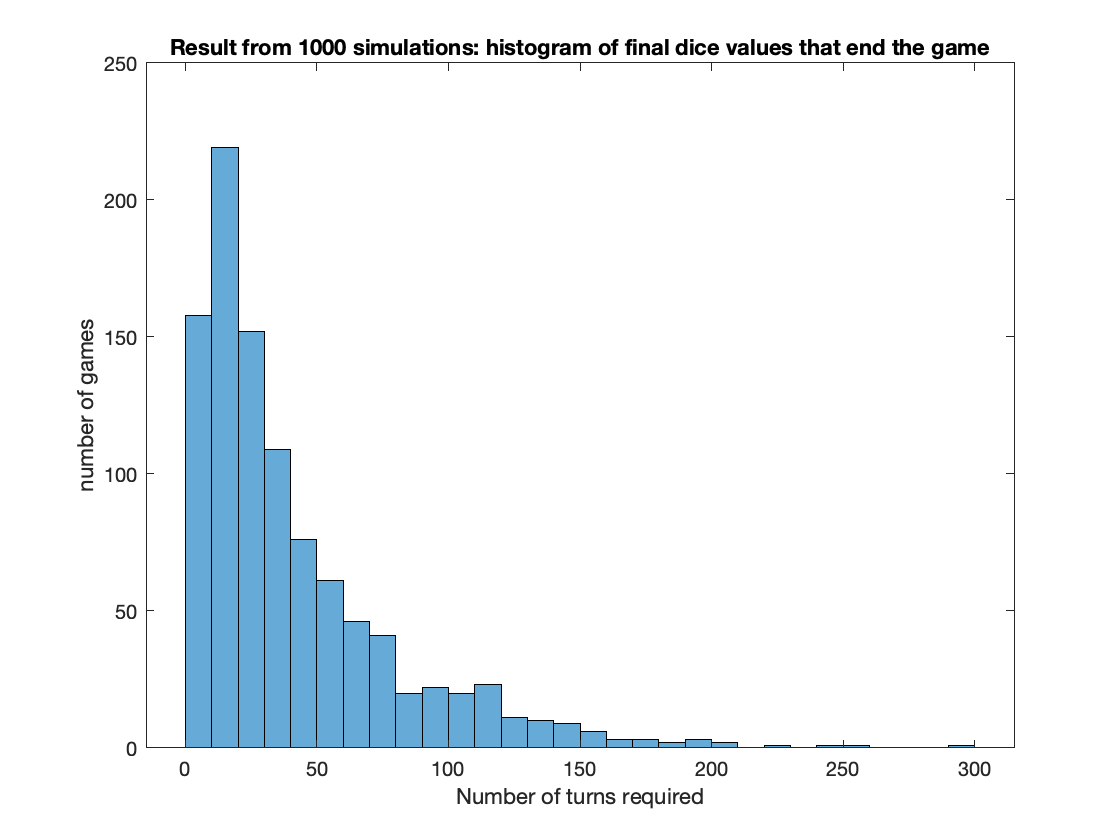

% Plot 2 - plot distributuion of number of turns 
histogram(numTurns)
ylabel('number of games')
xlabel('Number of turns required')
title('Result from 1000 simulations: histogram of final dice values that end the game')

#### 3) `for` loops

- **When do you use for loops? **Use a for loop when you know (or can calculate) how many iterations must be performed.

- **How does the index vector work?** The index vector simply specifies which values the loop index will take in each iteration. **See practice code.**

#### 4) `while` loops

- **When do you use while loops?** Use a while loop when you do not know ahead of time how many loop iterations to perform.

- **How do you keep track of iterations (or specific iterations)?** Use a counter! This is a variable initialized outside of the loop that can be incremented in each iteration performed. **See practice code.**

- How does a stopping condition relate to what is happening in the loop? 


%work while a conditional statement is true 
n = 0;
a = 0;
while n<5
    %keep track of when n is odd to perform tasks 
    if mod(n,2) == 1
        a = a+1;
    end
    n = n+1;

end

### Practice problem 2: numerical methods and root-finding

Numerical analysis is the domain of mathematics and computer science that creates, analyzes, and implements algorithms for solving numerically the problems of continuous mathematics. Numerically solving a complex math problem often involves iterating or following a given algorithm until it converges (hopefully) upon a solution, within some defined tolerance. 

One such application of numerical methods is root-finding, the algorithms for which may quickly find the root ($F\left(x\right)=0$) for some arbitrary function $F\left(x\right)$. Say we have a (potentially very nonlinear) function for which we want to find $F\left(x\right)=0$ quickly. The Newton-Raphson method searches for the root of a function by iteratively following where the tangent of a function crosses the `x` axis.  

Specifically,** the Newton-Raphson method has the following algorithm:**

- Pick an initial guess ($x_1$) of the root of a function.

- At that x value, calculate the tangent to the curve of the function.

- Find where the tangent to the curve intersects the x axis.This x value becomes $x_2$.

- At this new x value, repeat steps 2-3.

- When the new x value is not much different than the previous x value (as determined by some pre-defined tolerance), conclude that you have found an approximation for the root of the function. That is, you found a numerical approximation for the x value for which $F\left(x\right)=0$.

#### Visual depiction of the Newton-Raphson algorithm

**Iteration 1:** Make an initial guess, calculate where the tangent line at that point intersects x axis.

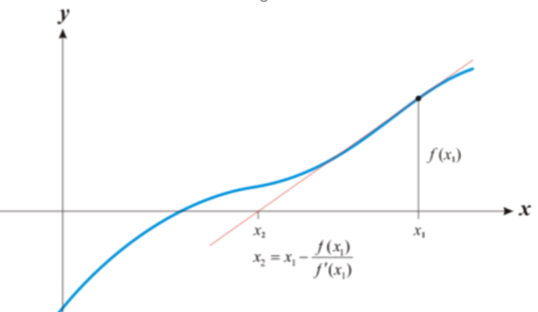

**Iteration 2:** Using this new x value, repeat the process

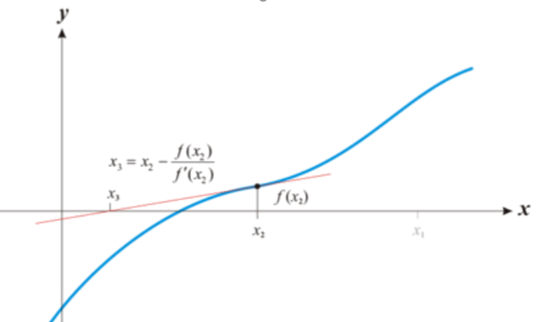

**Iteration 3:** The algorithm is beginning to converge on the root of $F\left(x\right)$.

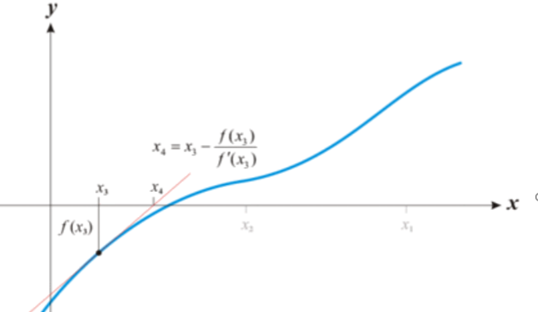

In these images, $x_n$ is the current guess for the root and $x_{n+1}$ is the next input in this iterative process. When $x_n$ -> $x_{n+1}$, we have found the root of the function.

#### Derivation of the Newton-Raphson method

1) The tangent line of the function at some point *x *can be written generally as:

                
$$y=m\;x+b$$


2) The slope, *m*, is simply the derivative of the function at `x``n:`

                
$$y=f^{\prime } \left(x_n \right)\;x+b$$


`3) `At *x = *`xn`*, y = f(*`xn`*)*, which allows us to solve for *b*

                
$$f\left(x_n \right)=f^{\prime } \left(x_n \right)x_n +b\longrightarrow b=f\left(x_n \right)-f^{\prime } \left(x_n \right)x_n$$


4) Substituting, we can write an equation for the tangent line in terms of $f\left(x_n \right)$,$f^{\prime } \left(x_n \right)$,$x_n$:

                
$$y=f^{\prime } \left(x_n \right)x+\left(f\left(x_n \right)-f^{\prime } \left(x_n \right)x_n \right)$$


5) In this algorithm, we solve for *y *= 0 for the tangent line. Thus, at y=0, and *x* = `x``n+1`:

                
$$0=f^{\prime } \left(x_n \right)x_{n+1} +\left(f\left(x_n \right)-f^{\prime } \left(x_n \right)x_n \right)$$


6) Rearranging the previous for `x``n+1` produces the Newton-Raphson equation:

                
$$x_{n+1} =x_n -\frac{f\left(x_n \right)}{f^{\prime } \left(x_n \right)}$$


**Thus, we have derived a numerical method for iterating until we converge on the root of a function.**

#### **Question 1**

**Use the Newton-raphson method to find the roots to the following equation:**

            
$$f\left(x\right)=x^4 +2{\left(x-2\right)}^2 -20$$


**PRO, Step 1****: ****P**lan, **P**repare, and **P**seudocode

Helpful tasks:

- We know the equation we want to solve for, can we plot it to get an idea of where the roots might be?

- We know the equation and the algorithm, can we write explicitly write out what the algorithm will look. That is, here:

            
$$\begin{array}{l}
f\left(x\right)=x^4 +2{\left(x-2\right)}^2 -20\\
f^{\prime } \left(x\right)={4x}^3 +4\left(x-2\right)
\end{array}$$


- We know the algorithm, but how is that converted into code? Write out pseudocode for what the script will look like.


% Step 1: specify initial guess

% Step 2: iterate until xn -> xn+1

% Step 3: xn + 1 from xn

% Step 4: compare xn and xn+1 to dtermine if loop should continue




**PRO, Step 2****: **w**R**ite **R**ough (increments of code) and **R**efine 

Helpful tasks:

- Starting with your pseudocode and what you know about the function, roughly fill in code.

% "Rough Solution:" use a for loop to solve this problem 

% Step 1: specify initial guess
xn = 3;

% Step 2: interate until xn -> xn+1
for k = 1:5
    %Step 3: evaluate function
    fn = xn^4 + 2*(xn-2)^2 - 20;
    
    % Step 3a: evaluate derivative
    f_prime_n = 4*xn^3 + 4*(xn-2);
    
    % Step 3b: calculate next x value
    xnplus1 = xn -fn/f_prime_n;
    
    % Step 4: update xn
    xn = xnplus1;
end
disp(xn)

**PRO, Step 3:** **O**ptimize and improve

We don't actually know how many loop iterations to perform ahead of time. Refine the code so that it is in the form of a `while` loop.

% Improved solution: use a while loop to iterate until convergence
% We will start by revisiting on Monday. The first is the approach we were
% heading towards in class before we ran out of time: using an if statement
% inside the while loop.

% Step 1: specify initial guess and other variables
xn = 3; % initial guess
keepIterating = 1; % Variable that specifies if we should keep iterating.
% We will set the value to zero if we meet some stopping criteria.

% Step 2: iterate until xn -> xn+1
while keepIterating
    
    % Step 3: evaluate function
    fn = xn^4 + 2*(xn-2)^2 - 20;
    %Step 3a: evaluate derivative
    f_prime_n = 4*xn^3 + 4*(xn-2);
    
    %Step 3b: calculate the next value of xn
    xnplus1 = xn - fn/f_prime_n;
    
    % Step 4: Evaluate if we have reached a stopping criteria. Note the
    % form of this relational expression
    if abs(xn - xnplus1) < 10^-5
        % One approach: use an if statement
        keepIterating = 0;
    end
    
    % Step 5: update xn and repeat
    xn = xnplus1;
end
disp(xn)


## Functions for this Livescript document

function [n, diceVal] = diceRollSimulator(max_n, n_sides)
%H1 help line, running a simulation until any number comes up max_n times
%in a row

%Simpler: roll dice until 3 1's land in a row 

%roll one dice 
n = 0;
numInARow = 0;
%previous value not 1-6
preDiceVal  = 0;

%evaluate dice face value 
% If dice face = 1 it is good unless restart
%continue to iterate until true
    while numInARow < max_n
        %have a variable to hold the pervious dice value 
        
        diceVal = randi(6);
        if diceVal == preDiceVal
            numInARow = numInARow + 1;
        else 
            numInARow = 1;
            preDiceVal = diceVal;
        end
        %counter
        n = n+1;
    end
end


